# LAB 9: NYQUIST STQBILITY CRITERION

%---------------------------------------
% Fill in your group number.
GroupNumber = 29;
% Fill in your student Name and ID.
Students(1).Name = 'Patrick Erath';
Students(1).ID = '260719203';
Students(2).Name = 'Ahmed Said';
Students(2).ID = '260665291';
%---------------------------------------

## **0. Objectives**

In the first part of this lab, we will use Nyquist stability criterion to analyze the stability of a unity feedback closed-loop system with a constant gain controller based on the Nyquist plot of the open-loop system. In the second part, we will look at an example on how the phase margin affects the robustness of the closed-loop of the system.

## **1 - Nyquist Stability Criterion**

Recall that stability of a closed-loop system can be inferred from the open-loop poles and Nyquist plot following the rule:

Let N be the number of counter clockwise (CCW) encirclements of (-1, 0) in the Nyquist plot, P the number of unstable poles of open-loop system, and Z the number of unstable poles of closed-loop system. We have:


$$ Z = P - N$$


## *Question 1 (5 marks)*

For the following systems. Define the transfer function, and plot the Nyquist plot. From the Nyquist plot, determine N, P, Z, decide if the closed-loop is stable or unstable, and report the phase margin and gain margin from the Nyquist plot if the system is stable. (help `nyquistplot`)

summary = struct([]);
s = tf('s');

1 - $$ L(s) = \displaystyle \frac{2}{s - 3} $$

Idx = 1;

L(Idx)=2/(s-3) % Define the transfer function


L =
 
  From input 1 to output:
    2
  -----
  s - 3
 
  From input 2 to output:
        4
  -------------
  s^2 + 7 s + 6
 
  From input 3 to output:
       3
  -----------
  s^2 + s - 2
 
  From input 4 to output:
              2
  -------------------------
  s^3 + 2.5 s^2 + 0.5 s - 1
 
  From input 5 to output:
    10 s + 10
  --------------
  s^2 - 8 s + 16
 
  From input 6 to output:
          s + 4
  ---------------------
  s^3 - 4 s^2 + 5 s - 2
 
  From input 7 to output:
        5 s + 15
  --------------------
  s^3 - s^2 - 2 s - 12
 
  From input 8 to output:
  0
 
  From input 9 to output:
  0
 
  From input 10 to output:
                    5
  exp(-1*s) * -------------
              s^2 + 3 s + 2
 
Continuous-time transfer function.



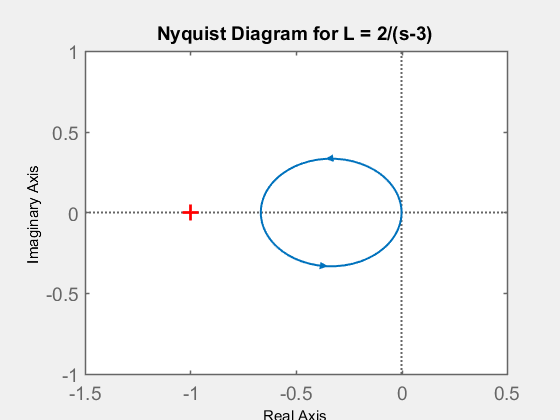


figure;
set(gcf, 'Visible', 'off');
% Draw the Nyquist plot
nyquistplot(L(Idx))
customizeNyquistPlot(L(Idx), [-1.5, 0.5], [-1, 1]);

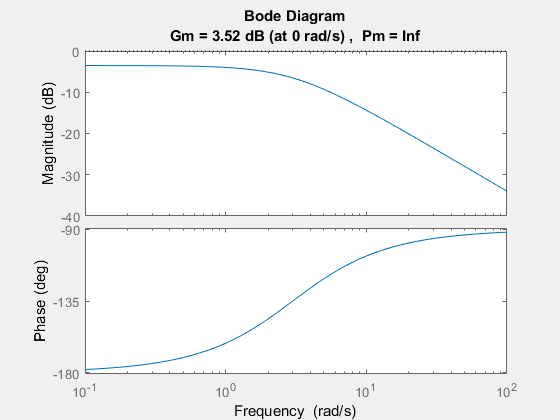

% Answer P, N, Z, stable?, PM (only if stable), GM (only if stable)
summary(Idx).Index = Idx;
summary(Idx).Transfer_Function = tf2str(L(Idx));

summary(Idx).P = 1; % Write P here.
summary(Idx).N = 0; % Write N here.
summary(Idx).Z = 1; % Write Z here.
summary(Idx).Stable = 'No'; % Write 'Yes' or 'No'.
margin(L(Idx))

summary(Idx).PM = NaN; % Write Phase Margin if applicable
summary(Idx).GM = NaN; % Write Gain Margin if applicable


disp(struct2table(summary(Idx)));

    Index    Transfer_Function    P    N    Z    Stable    PM      GM 
    _____    _________________    _    _    _    ______    ___    ____

    1        "2/(s-3)"            1    0    1    No        Inf    -1.5



2 - $$ L(s) = \displaystyle \frac{3}{s^2+s-2} $$

Idx = 3;

L(Idx)=3/(s^2+s-2) % Define the transfer function


L =
 
  From input 1 to output:
    2
  -----
  s - 3
 
  From input 2 to output:
        4
  -------------
  s^2 + 7 s + 6
 
  From input 3 to output:
       3
  -----------
  s^2 + s - 2
 
  From input 4 to output:
              2
  -------------------------
  s^3 + 2.5 s^2 + 0.5 s - 1
 
  From input 5 to output:
    10 s + 10
  --------------
  s^2 - 8 s + 16
 
  From input 6 to output:
          s + 4
  ---------------------
  s^3 - 4 s^2 + 5 s - 2
 
  From input 7 to output:
        5 s + 15
  --------------------
  s^3 - s^2 - 2 s - 12
 
  From input 8 to output:
  0
 
  From input 9 to output:
  0
 
  From input 10 to output:
                    5
  exp(-1*s) * -------------
              s^2 + 3 s + 2
 
Continuous-time transfer function.



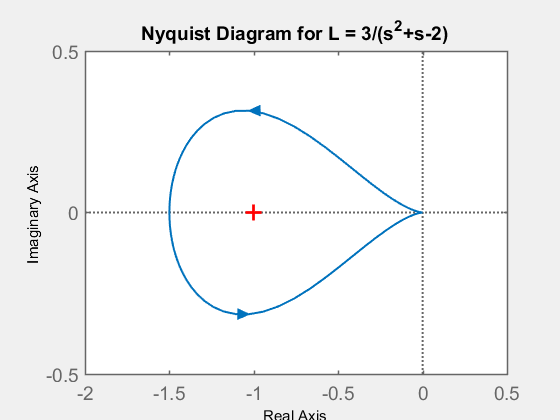


figure;
set(gcf, 'Visible', 'off');
% Draw the Nyquist plot
nyquistplot(L(Idx))
customizeNyquistPlot(L(Idx), [-2, 0.5], [-0.5, 0.5]);

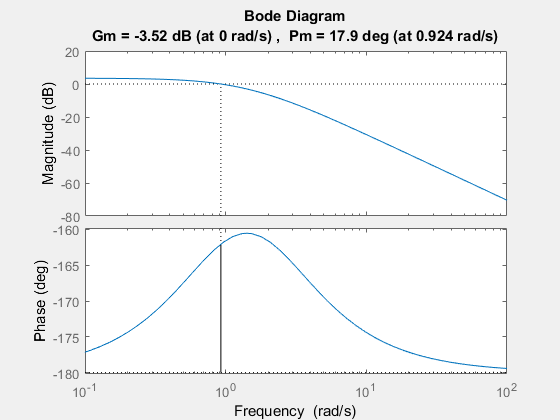

% Answer P, N, Z, stable?, PM (only if stable), GM (only if stable)
summary(Idx).Index = Idx;
summary(Idx).Transfer_Function = tf2str(L(Idx));

summary(Idx).P = 1; % Write P here.
summary(Idx).N = 1; % Write N here.
summary(Idx).Z = 0; % Write Z here.
summary(Idx).Stable = 'Yes'; % Write 'Yes' or 'No'.
margin(L(Idx))

summary(Idx).PM = 17.9 % Write Phase Margin if applicable

summary = 1×5 struct array with fields:
    Index
    Transfer_Function
    P
    N
    Z
    Stable
    PM
    GM


summary(Idx).GM = 2/3; % Write Gain Margin if applicable


disp(struct2table(summary(Idx)));

    Index    Transfer_Function    P    N    Z    Stable     PM       GM   
    _____    _________________    _    _    _    ______    ____    _______

    3        "3/(s^2+s-2)"        1    1    0    Yes       17.9    0.66667



3 - $$ L(s) = \displaystyle \frac{4}{(s + 1)(s+6)} $$

Idx = 2;

L(Idx)= 4/((s+1)*(s+6))% Define the transfer function


L =
 
  From input 1 to output:
    2
  -----
  s - 3
 
  From input 2 to output:
        4
  -------------
  s^2 + 7 s + 6
 
  From input 3 to output:
       3
  -----------
  s^2 + s - 2
 
  From input 4 to output:
              2
  -------------------------
  s^3 + 2.5 s^2 + 0.5 s - 1
 
  From input 5 to output:
    10 s + 10
  --------------
  s^2 - 8 s + 16
 
  From input 6 to output:
          s + 4
  ---------------------
  s^3 - 4 s^2 + 5 s - 2
 
  From input 7 to output:
        5 s + 15
  --------------------
  s^3 - s^2 - 2 s - 12
 
  From input 8 to output:
  0
 
  From input 9 to output:
  0
 
  From input 10 to output:
                    5
  exp(-1*s) * -------------
              s^2 + 3 s + 2
 
Continuous-time transfer function.



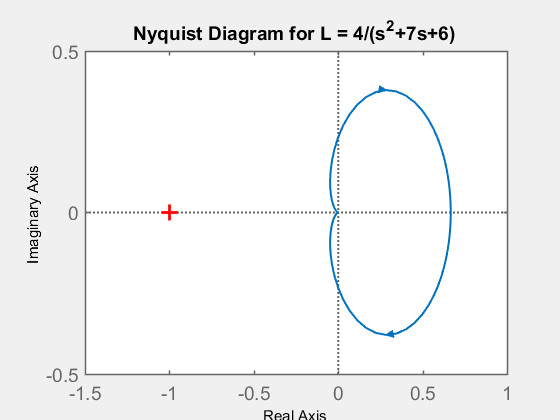


figure;
set(gcf, 'Visible', 'off');
% Draw the Nyquist plot
nyquistplot(L(Idx))
customizeNyquistPlot(L(Idx), [-1.5, 1], [-0.5, 0.5]);

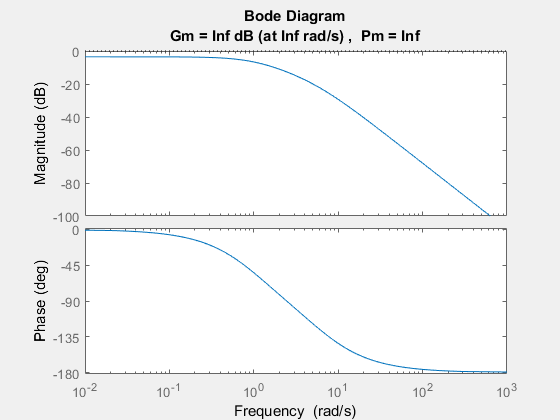

% Answer P, N, Z, stable?, PM (only if stable), GM (only if stable)
summary(Idx).Index = Idx;
summary(Idx).Transfer_Function = tf2str(L(Idx));

summary(Idx).P = 0; % Write P here.
summary(Idx).N = 0; % Write N here.
summary(Idx).Z = 0; % Write Z here.
summary(Idx).Stable = 'Yes'; % Write 'Yes' or 'No'.
margin(L(Idx))

summary(Idx).PM = Inf; % Write Phase Margin if applicable
summary(Idx).GM = Inf; % Write Gain Margin if applicable


disp(struct2table(summary(Idx)));

    Index    Transfer_Function    P    N    Z    Stable    PM     GM 
    _____    _________________    _    _    _    ______    ___    ___

    2        "4/(s^2+7s+6)"       0    0    0    Yes       Inf    Inf



4 - $$ L(s) = \displaystyle \frac{2}{(s+1)(s+2)(s-\displaystyle \frac{1}{2})} $$

Idx = 4;

L(Idx)=2/((s+1)*(s+2)*(s-0.5)) % Define the transfer function


L =
 
  From input 1 to output:
    2
  -----
  s - 3
 
  From input 2 to output:
        4
  -------------
  s^2 + 7 s + 6
 
  From input 3 to output:
       3
  -----------
  s^2 + s - 2
 
  From input 4 to output:
              2
  -------------------------
  s^3 + 2.5 s^2 + 0.5 s - 1
 
  From input 5 to output:
    10 s + 10
  --------------
  s^2 - 8 s + 16
 
  From input 6 to output:
          s + 4
  ---------------------
  s^3 - 4 s^2 + 5 s - 2
 
  From input 7 to output:
        5 s + 15
  --------------------
  s^3 - s^2 - 2 s - 12
 
  From input 8 to output:
  0
 
  From input 9 to output:
  0
 
  From input 10 to output:
                    5
  exp(-1*s) * -------------
              s^2 + 3 s + 2
 
Continuous-time transfer function.



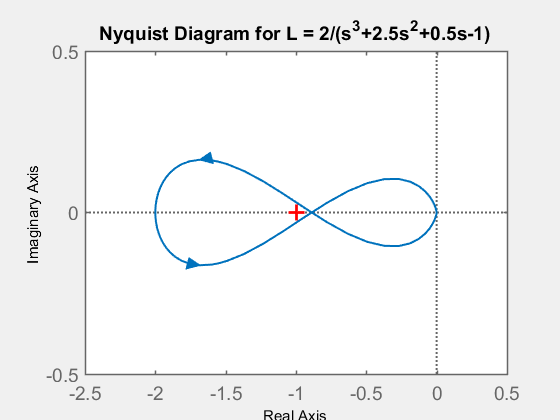


figure;
set(gcf, 'Visible', 'off');
% Draw the Nyquist plot
nyquistplot(L(Idx))
customizeNyquistPlot(L(Idx), [-2.5, 0.5], [-0.5, 0.5]);

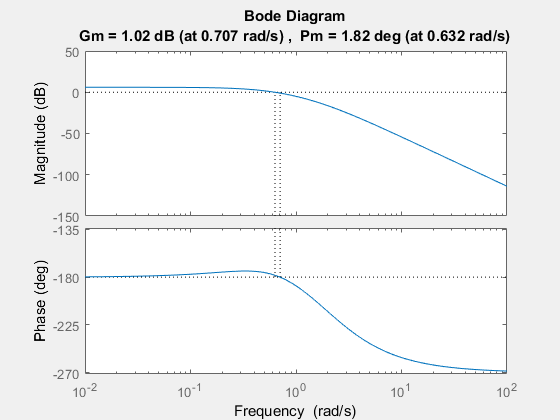

% Answer P, N, Z, stable?, PM (only if stable), GM (only if stable)
summary(Idx).Index = Idx;
summary(Idx).Transfer_Function = tf2str(L(Idx));

summary(Idx).P = 1; % Write P here.
summary(Idx).N = 1; % Write N here.
summary(Idx).Z = 0; % Write Z here.
summary(Idx).Stable = 'Yes'; % Write 'Yes' or 'No'.
margin(L(Idx))

summary(Idx).PM = 1.82; % Write Phase Margin if applicable
summary(Idx).GM = 1.12; % Write Gain Margin if applicable


disp(struct2table(summary(Idx)));

    Index       Transfer_Function       P    N    Z    Stable     PM      GM 
    _____    _______________________    _    _    _    ______    ____    ____

    4        "2/(s^3+2.5s^2+0.5s-1)"    1    1    0    Yes       1.82    1.12



5 - $$ L(s) = \displaystyle \frac{10(s+1)}{(s-4)^2} $$

Idx = 5;

L(Idx)=10*(s+1)/(s-4)^2 % Define the transfer function


L =
 
  From input 1 to output:
    2
  -----
  s - 2
 
  From input 2 to output:
  0
 
  From input 3 to output:
  0
 
  From input 4 to output:
  0
 
  From input 5 to output:
    10 s + 10
  --------------
  s^2 - 8 s + 16
 
Continuous-time transfer function.



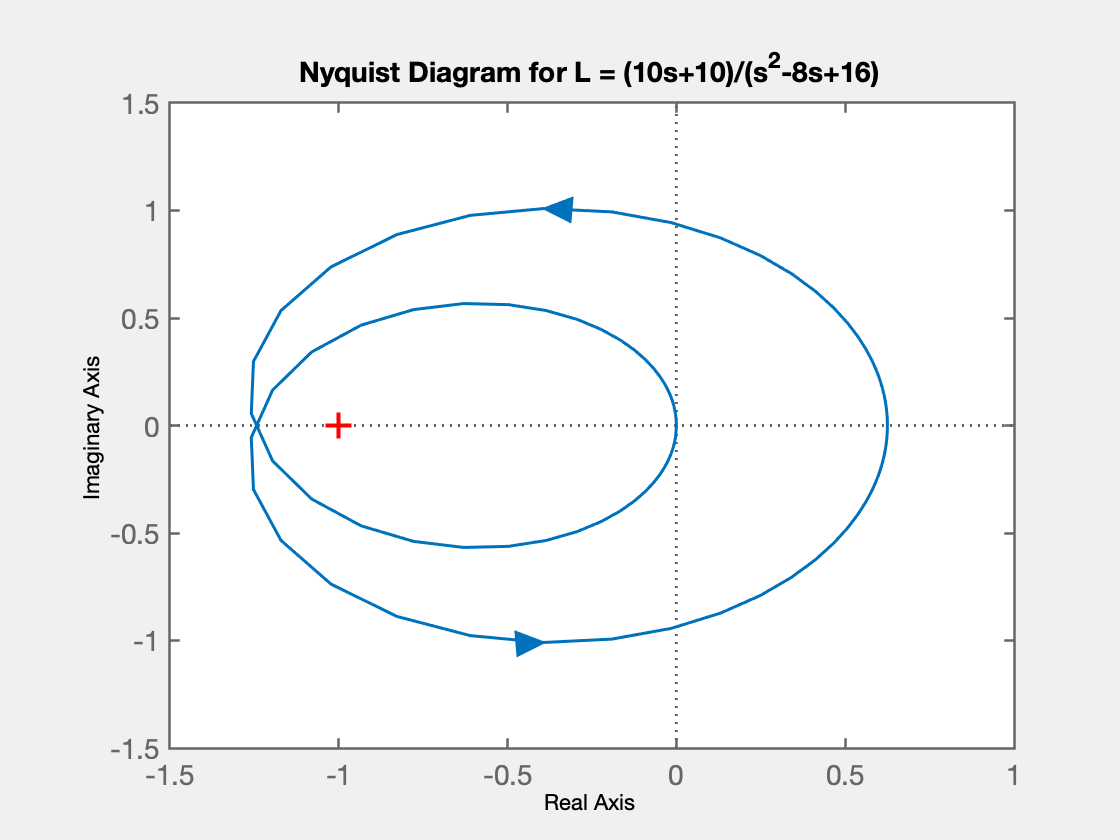


figure;
set(gcf, 'Visible', 'off');
% Draw the Nyquist plot
nyquistplot(L(Idx))
customizeNyquistPlot(L(Idx), [-1.5, 1.0], [-1.5, 1.5]);

% Answer P, N, Z, stable?, PM (only if stable), GM (only if stable)
summary(Idx).Index = Idx;
summary(Idx).Transfer_Function = tf2str(L(Idx));

summary(Idx).P = 2; % Write P here.
summary(Idx).N = 2; % Write N here.
summary(Idx).Z = 0; % Write Z here.
summary(Idx).Stable = 'Yes'; % Write 'Yes' or 'No'.
summary(Idx).PM = 30.4; % Write Phase Margin if applicable
summary(Idx).GM = 1/1.243314; % Write Gain Margin if applicable


disp(struct2table(summary(Idx)));

    Index      Transfer_Function       P    N    Z    Stable     PM       GM  
    _____    ______________________    _    _    _    ______    ____    ______

    5        "(10s+10)/(s^2-8s+16)"    2    2    0    Yes       30.4    0.8043



6 - $$ L(s) = \displaystyle \frac{s+4}{(s-1)^2(s-2)} $$

Idx = 6;

L(Idx)=(s+4)/((s-1)^2*(s-2)) % Define the transfer function


L =
 
  From input 1 to output:
    2
  -----
  s - 3
 
  From input 2 to output:
        4
  -------------
  s^2 + 7 s + 6
 
  From input 3 to output:
       3
  -----------
  s^2 + s - 2
 
  From input 4 to output:
              2
  -------------------------
  s^3 + 2.5 s^2 + 0.5 s - 1
 
  From input 5 to output:
    10 s + 10
  --------------
  s^2 - 8 s + 16
 
  From input 6 to output:
          s + 4
  ---------------------
  s^3 - 4 s^2 + 5 s - 2
 
  From input 7 to output:
        5 s + 15
  --------------------
  s^3 - s^2 - 2 s - 12
 
  From input 8 to output:
  0
 
  From input 9 to output:
  0
 
  From input 10 to output:
                    5
  exp(-1*s) * -------------
              s^2 + 3 s + 2
 
Continuous-time transfer function.



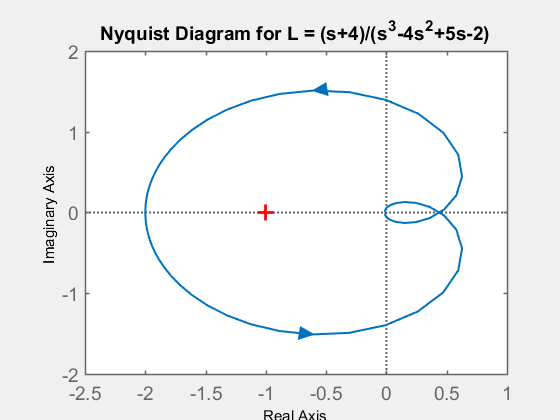


figure;
set(gcf, 'Visible', 'off');
% Draw the Nyquist plot
nyquistplot(L(Idx))
customizeNyquistPlot(L(Idx), [-2.5, 1], [-2, 2]);

% Answer P, N, Z, stable?, PM (only if stable), GM (only if stable)
summary(Idx).Index = Idx;
summary(Idx).Transfer_Function = tf2str(L(Idx));

summary(Idx).P = 3; % Write P here.
summary(Idx).N = 1; % Write N here.
summary(Idx).Z = 2; % Write Z here.
summary(Idx).Stable = 'No'; % Write 'Yes' or 'No'.
summary(Idx).PM = NaN; % Write Phase Margin if applicable
summary(Idx).GM = NaN; % Write Gain Margin if applicable


disp(struct2table(summary(Idx)));

    Index       Transfer_Function       P    N    Z    Stable    PM      GM 
    _____    _______________________    _    _    _    ______    ___    ____

    6        "(s+4)/(s^3-4s^2+5s-2)"    3    1    2    No        NaN    -0.5



7 - $$ L(s) = \displaystyle \frac{5(s+3)}{(s-3)(s^2+2s+4)} $$

Idx = 7;

L(Idx)=(5*(s+3))/((s-3)*(s^2+2*s+4)) % Define the transfer function


L =
 
  From input 1 to output:
    2
  -----
  s - 3
 
  From input 2 to output:
        4
  -------------
  s^2 + 7 s + 6
 
  From input 3 to output:
       3
  -----------
  s^2 + s - 2
 
  From input 4 to output:
              2
  -------------------------
  s^3 + 2.5 s^2 + 0.5 s - 1
 
  From input 5 to output:
    10 s + 10
  --------------
  s^2 - 8 s + 16
 
  From input 6 to output:
          s + 4
  ---------------------
  s^3 - 4 s^2 + 5 s - 2
 
  From input 7 to output:
        5 s + 15
  --------------------
  s^3 - s^2 - 2 s - 12
 
  From input 8 to output:
  0
 
  From input 9 to output:
  0
 
  From input 10 to output:
                    5
  exp(-1*s) * -------------
              s^2 + 3 s + 2
 
Continuous-time transfer function.



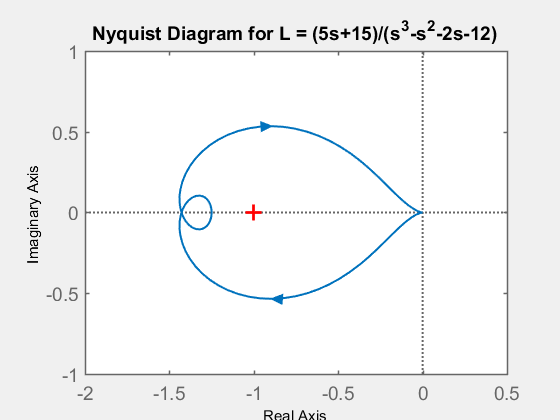


figure;
set(gcf, 'Visible', 'off');
% Draw the Nyquist plot
nyquistplot(L(Idx))
customizeNyquistPlot(L(Idx), [-2, 0.5], [-1, 1]);

% Answer P, N, Z, stable?, PM (only if stable), GM (only if stable)
summary(Idx).Index = Idx;
summary(Idx).Transfer_Function = tf2str(L(Idx));

summary(Idx).P = 1; % Write P here.
summary(Idx).N = -1; % Write N here.
summary(Idx).Z = 2; % Write Z here.
summary(Idx).Stable = 'No'; % Write 'Yes' or 'No'.
summary(Idx).PM = NaN; % Write Phase Margin if applicable
summary(Idx).GM = NaN; % Write Gain Margin if applicable


disp(struct2table(summary(Idx)));

    Index      Transfer_Function       P    N     Z    Stable    PM     GM 
    _____    ______________________    _    __    _    ______    ___    ___

    5        "(10s+10)/(s^2-8s+16)"    1    -1    2    No        NaN    NaN



8 - $$ L(s) = \displaystyle \frac{5(s+3)}{(s-2)(s^2+3s+6)} $$

Idx = 8;

L(Idx)=(5*(s+3))/((s-2)*(s^2+3*s+6)) % Define the transfer function


L =
 
  From input 1 to output:
    2
  -----
  s - 3
 
  From input 2 to output:
        4
  -------------
  s^2 + 7 s + 6
 
  From input 3 to output:
       3
  -----------
  s^2 + s - 2
 
  From input 4 to output:
              2
  -------------------------
  s^3 + 2.5 s^2 + 0.5 s - 1
 
  From input 5 to output:
    10 s + 10
  --------------
  s^2 - 8 s + 16
 
  From input 6 to output:
          s + 4
  ---------------------
  s^3 - 4 s^2 + 5 s - 2
 
  From input 7 to output:
        5 s + 15
  --------------------
  s^3 - s^2 - 2 s - 12
 
  From input 8 to output:
     5 s + 15
  --------------
  s^3 + s^2 - 12
 
  From input 9 to output:
  0
 
  From input 10 to output:
                    5
  exp(-1*s) * -------------
              s^2 + 3 s + 2
 
Continuous-time transfer function.



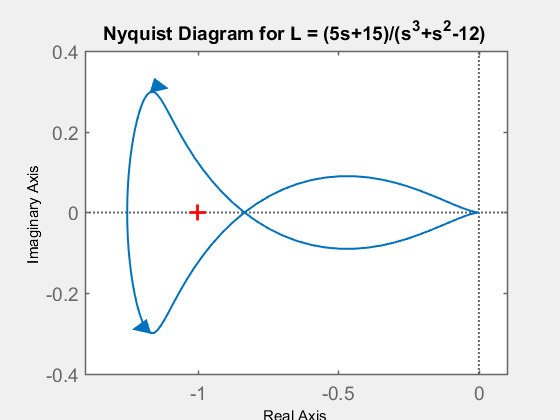


figure;
set(gcf, 'Visible', 'off');
% Draw the Nyquist plot
nyquistplot(L(Idx))
customizeNyquistPlot(L(Idx), [-1.4, 0.1], [-0.4, 0.4]);

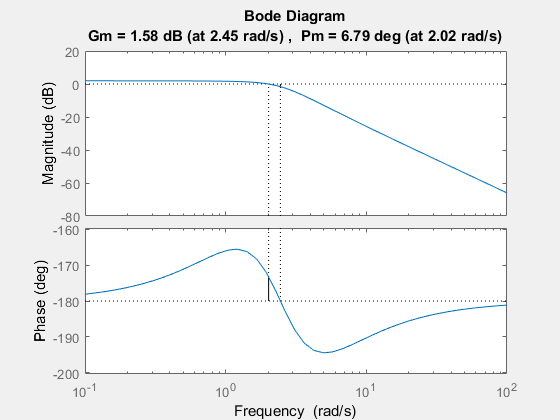

% Answer P, N, Z, stable?, PM (only if stable), GM (only if stable)
summary(Idx).Index = Idx;
summary(Idx).Transfer_Function = tf2str(L(Idx));

summary(Idx).P = 1; % Write P here.
summary(Idx).N = 1; % Write N here.
summary(Idx).Z = 0; % Write Z here.
summary(Idx).Stable = 'Yes'; % Write 'Yes' or 'No'.
margin(L(Idx))

summary(Idx).PM = 6.79; % Write Phase Margin if applicable
summary(Idx).GM = 1.89; % Write Gain Margin if applicable


disp(struct2table(summary(Idx)));

    Index      Transfer_Function       P    N    Z    Stable     PM      GM 
    _____    ______________________    _    _    _    ______    ____    ____

    8        "(5s+15)/(s^3+s^2-12)"    1    1    0    Yes       6.79    1.89



9 - $$ L(s) = \displaystyle \frac{35(s-4)(s+1)}{(s+3)(s+2)(s-5)} $$

Idx = 9;

L(Idx)=(35*(s-4)*(s+1))/((s+3)*(s+2)*(s-5)) % Define the transfer function


L =
 
  From input 1 to output:
    2
  -----
  s - 3
 
  From input 2 to output:
        4
  -------------
  s^2 + 7 s + 6
 
  From input 3 to output:
       3
  -----------
  s^2 + s - 2
 
  From input 4 to output:
              2
  -------------------------
  s^3 + 2.5 s^2 + 0.5 s - 1
 
  From input 5 to output:
    10 s + 10
  --------------
  s^2 - 8 s + 16
 
  From input 6 to output:
          s + 4
  ---------------------
  s^3 - 4 s^2 + 5 s - 2
 
  From input 7 to output:
        5 s + 15
  --------------------
  s^3 - s^2 - 2 s - 12
 
  From input 8 to output:
     5 s + 15
  --------------
  s^3 + s^2 - 12
 
  From input 9 to output:
  35 s^2 - 105 s - 140
  --------------------
    s^3 - 19 s - 30
 
  From input 10 to output:
                    5
  exp(-1*s) * -------------
              s^2 + 3 s + 2
 
Continuous-time transfer function.



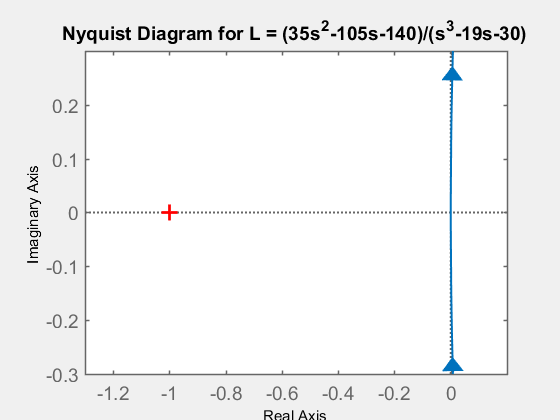


figure;
set(gcf, 'Visible', 'off');
% Draw the Nyquist plot
nyquistplot(L(Idx))
customizeNyquistPlot(L(Idx), [-1.3, 0.2], [-0.3, 0.3]);

% Answer P, N, Z, stable?, PM (only if stable), GM (only if stable)
summary(Idx).Index = Idx;
summary(Idx).Transfer_Function = tf2str(L(Idx));

summary(Idx).P = 1; % Write P here.
summary(Idx).N = 0; % Write N here.
summary(Idx).Z = 1; % Write Z here.
summary(Idx).Stable = 'No'; % Write 'Yes' or 'No'.
summary(Idx).PM = NaN; % Write Phase Margin if applicable
summary(Idx).GM = NaN; % Write Gain Margin if applicable


disp(struct2table(summary(Idx)));

    Index           Transfer_Function           P    N    Z    Stable    PM     GM 
    _____    _______________________________    _    _    _    ______    ___    ___

    9        "(35s^2-105s-140)/(s^3-19s-30)"    1    0    1    No        NaN    NaN



10 - $$ L(s) = \displaystyle \frac{5e^{-s}}{(s+1)(s+2)} $$

Idx = 10;

L(Idx)=(5*exp(-s))/((s+1)*(s+2)) % Define the transfer function


L =
 
  From input 1 to output:
    2
  -----
  s - 3
 
  From input 2 to output:
        4
  -------------
  s^2 + 7 s + 6
 
  From input 3 to output:
       3
  -----------
  s^2 + s - 2
 
  From input 4 to output:
              2
  -------------------------
  s^3 + 2.5 s^2 + 0.5 s - 1
 
  From input 5 to output:
    10 s + 10
  --------------
  s^2 - 8 s + 16
 
  From input 6 to output:
          s + 4
  ---------------------
  s^3 - 4 s^2 + 5 s - 2
 
  From input 7 to output:
        5 s + 15
  --------------------
  s^3 - s^2 - 2 s - 12
 
  From input 8 to output:
     5 s + 15
  --------------
  s^3 + s^2 - 12
 
  From input 9 to output:
  35 s^2 - 105 s - 140
  --------------------
    s^3 - 19 s - 30
 
  From input 10 to output:
                    5
  exp(-1*s) * -------------
              s^2 + 3 s + 2
 
Continuous-time transfer function.



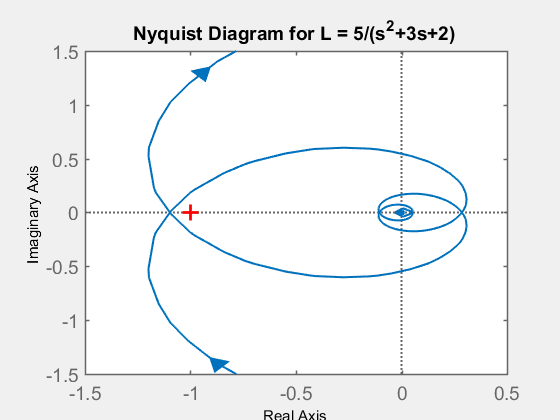


figure;
set(gcf, 'Visible', 'off');
% Draw the Nyquist plot
nyquistplot(L(Idx))
customizeNyquistPlot(L(Idx), [-1.5, 0.5], [-1.5, 1.5]);

% Answer P, N, Z, stable?, PM (only if stable), GM (only if stable)
summary(Idx).Index = Idx;
summary(Idx).Transfer_Function = tf2str(L(Idx));

summary(Idx).P = 0; % Write P here.
summary(Idx).N = -1; % Write N here.
summary(Idx).Z = 1; % Write Z here.
summary(Idx).Stable = 'No'; % Write 'Yes' or 'No'.
summary(Idx).PM = NaN; % Write Phase Margin if applicable
summary(Idx).GM = NaN; % Write Gain Margin if applicable


disp(struct2table(summary(Idx)));

    Index    Transfer_Function    P    N     Z    Stable    PM     GM 
    _____    _________________    _    __    _    ______    ___    ___

    10       "5/(s^2+3s+2)"       0    -1    1    No        NaN    NaN



## **2 - Design for Angular Position Control**

We consider the previously presented DC Motor with the state space model

param.Kt = 0.034; % Torque proportionality constant (Kg m2 /s2/A) (N.m/A)
param.Ke = 0.034; % Back electromotive proportionality constant (V/rad/s)
param.L = 0.018; % Electric inductance (H)
param.R = 8.4; % Terminal resistance (Ohm)
param.J = 2e-05; % Rotor moment of inertia (kg.m2)
param.b = 1e-06; % Rotor viscous friction constant (Kg.m2/s) (N.m.s)

A = [ ...
    0, 1, 0; ...
    0, -param.b / param.J, param.Kt / param.J; ...
    0, -param.Ke / param.L, -param.R / param.L];


B = [ ...
    0; ...
    0; ...
    1 / param.L];


C = [1, 0, 0];

D = 0;

## *Question 2 (0.5 marks)*

Draw the Nyquist plot of the transfer function of the DC Motor $H_{ol}$.

Hol = ss(A,B,C,D) % define the transfer function


Hol =
 
  A = 
           x1      x2      x3
   x1       0       1       0
   x2       0   -0.05    1700
   x3       0  -1.889  -466.7
 
  B = 
          u1
   x1      0
   x2      0
   x3  55.56
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



Hol = tf(Hol)


Hol =
 
          9.444e04
  ------------------------
  s^3 + 466.7 s^2 + 3234 s
 
Continuous-time transfer function.



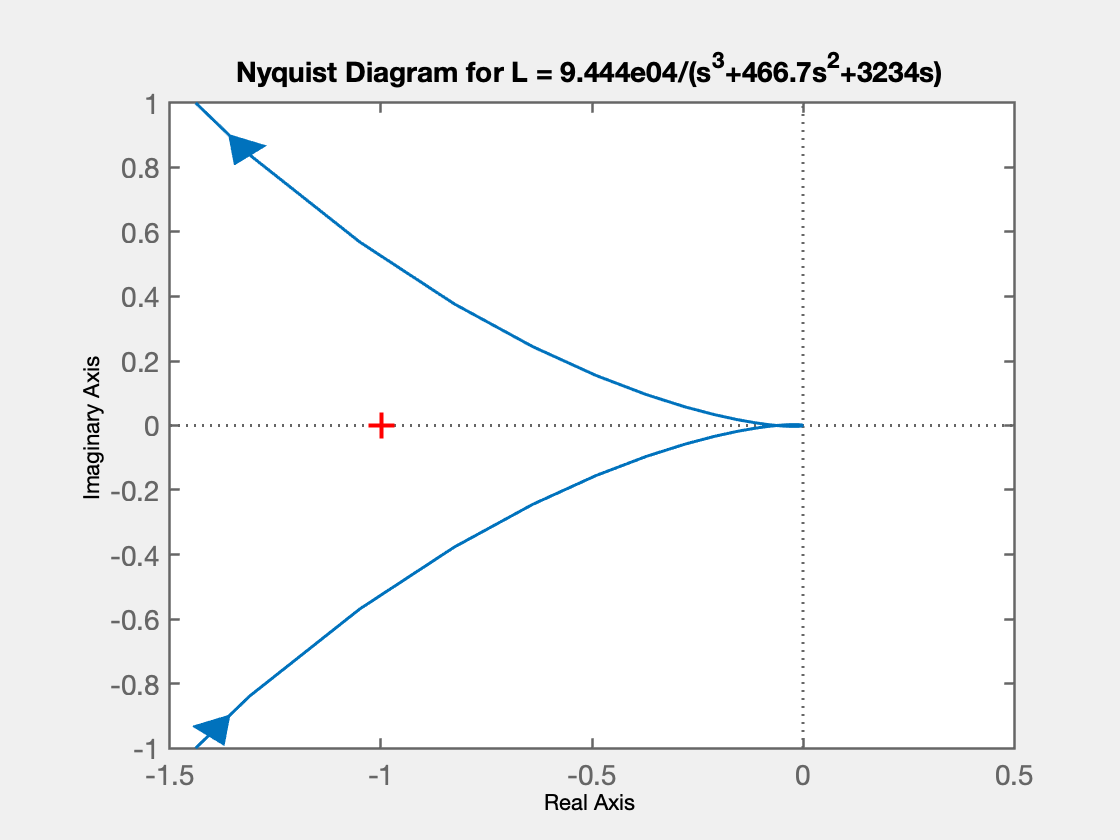

figure;
set(gcf, 'Visible', 'off');
% Draw the Nyquist plot
nyquistplot(Hol);
customizeNyquistPlot(Hol, [-1.5, 0.5], [-1, 1]);

## *Question 3 (2 marks)*

From the Nyquist plot, what is the value of the unity feedback $K$ which makes the closed-loop system unstable.

K = 1/(0.0626)

K = 15.9744

## *Question 4 (1.5 marks)*

For the follwoing values of $K$ = [0.01 0.1 1 10], draw the Nyquist plot of $K H_{ol}$ and read the phase margin from the plot.

K %0.01; 0.1; 1; 10;

K = 15.9744


[GM1, PM1] = margin(0.01*Hol)

GM1 = 1.5984e+03

PM1 = 87.5894

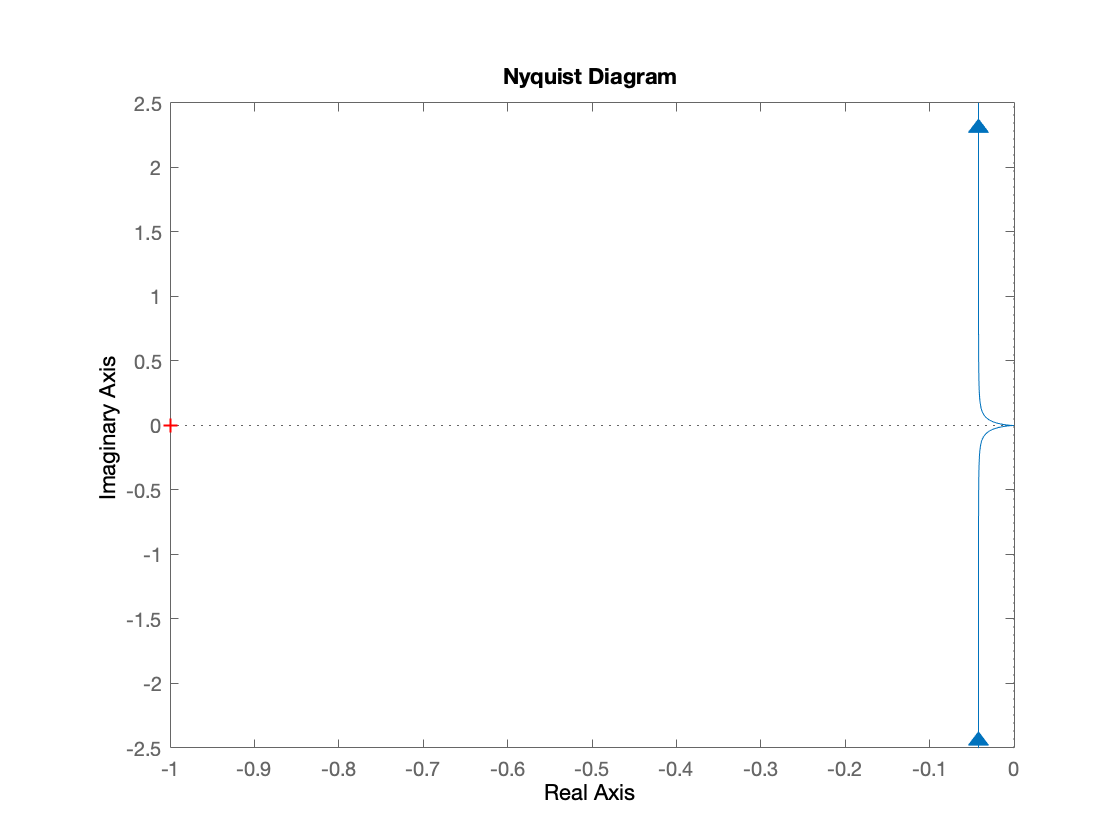

nyquist(0.01*Hol)


[GM2, PM2] = margin(0.1*Hol)

GM2 = 159.8367

PM2 = 68.5038

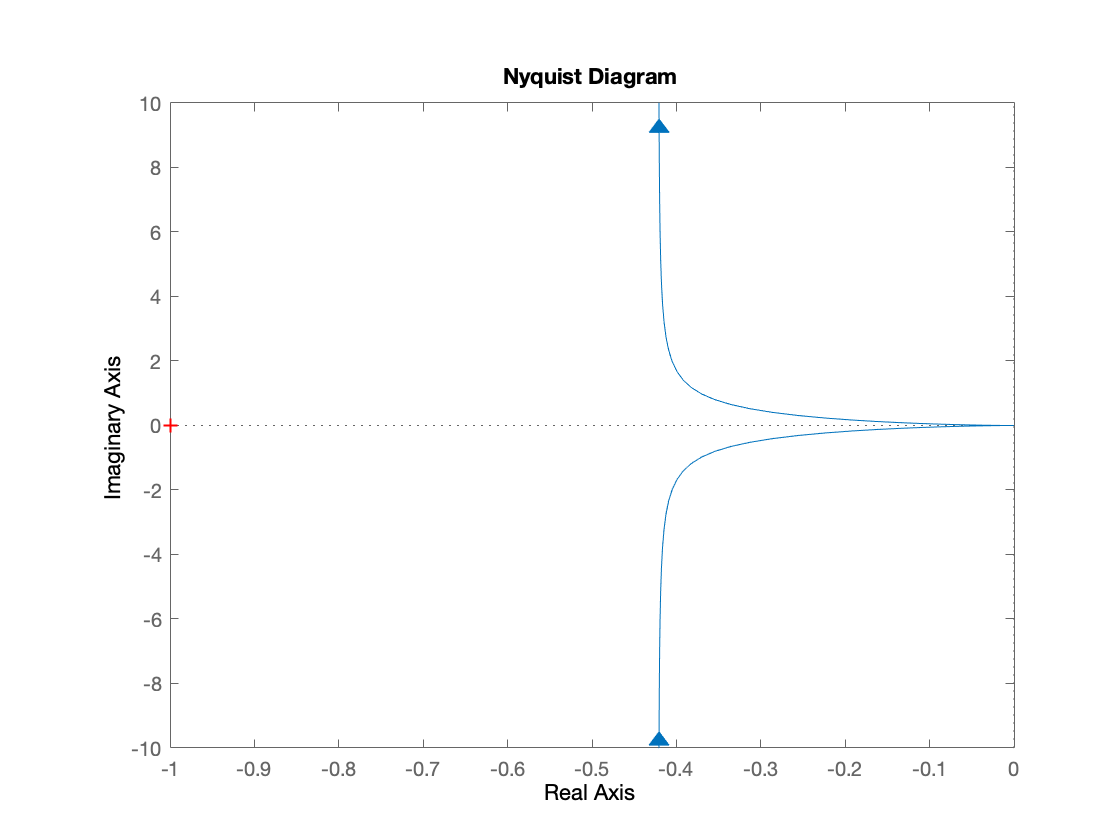

nyquist(0.1*Hol)


[GM3, PM3] = margin(Hol)

GM3 = 15.9837

PM3 = 25.8570

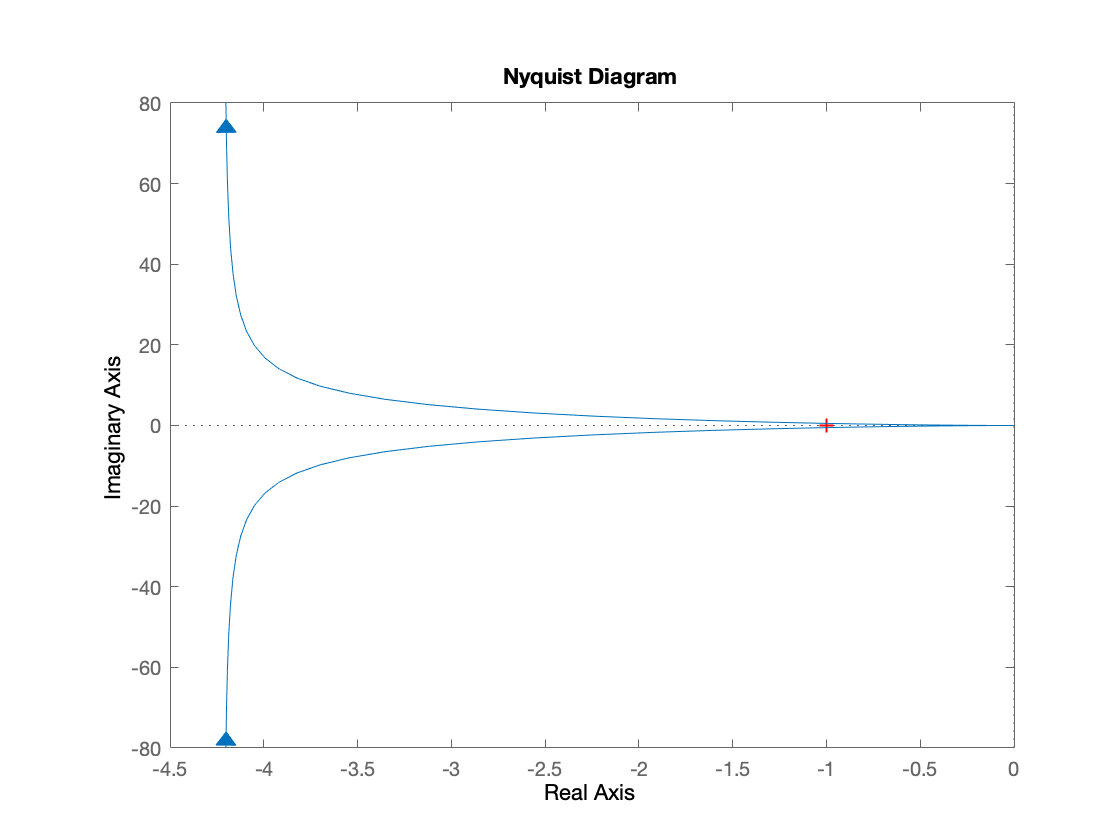

nyquist(Hol)


[GM4, PM4] = margin(10*Hol)

GM4 = 1.5984

PM4 = 3.3166

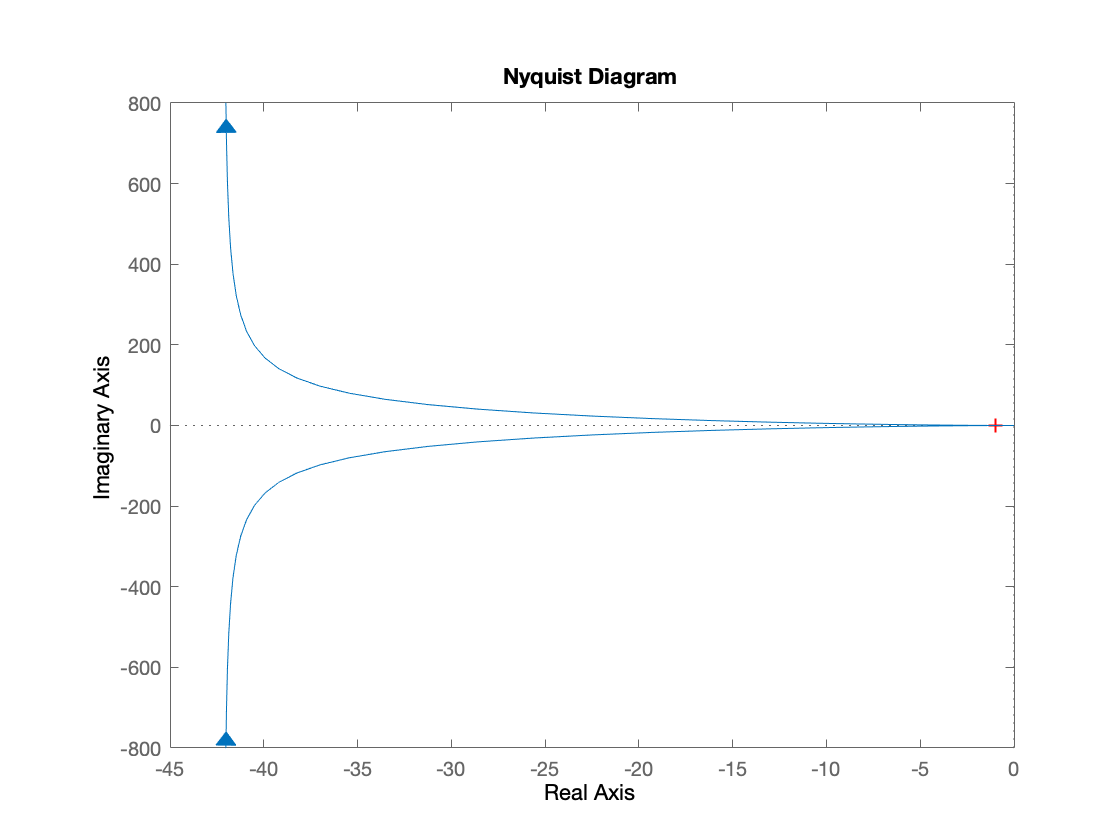

nyquist(10*Hol)

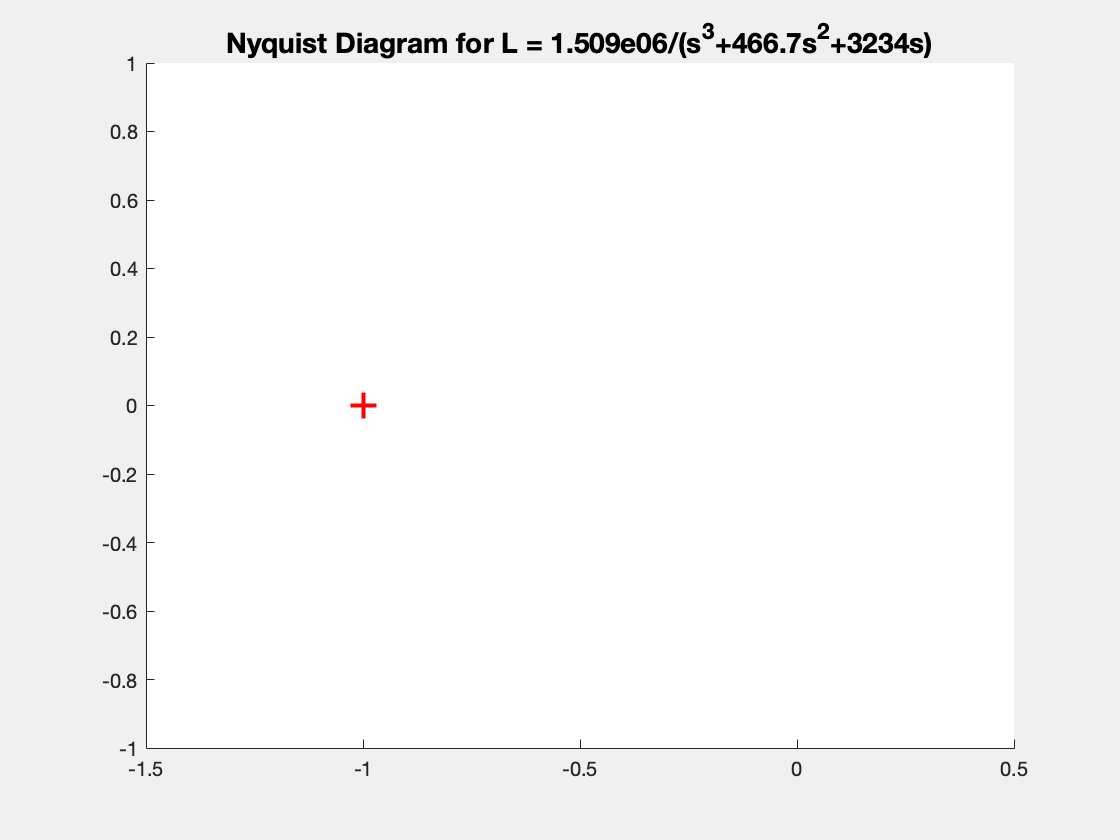


Hol = tf(ss(A, B, C, D));
figure;
set(gcf, 'Visible', 'off');
% Draw the Nyquist plot

customizeNyquistPlot(K*Hol, [-1.5, 0.5], [-1, 1]);

% Write the phase margin here (PM should be an array of 4 values):

PM = [PM1, PM2, PM3, PM4]

## *Question 5 (1 marks)*

Run the code to simulate the closed-loop system for each value of $K$ = [0.01 0.1 1 10]. How does the phase margin relates to the stability of the closed-loop system ?

K=16 %0.01; 0.1; 1; 10;

K = 16

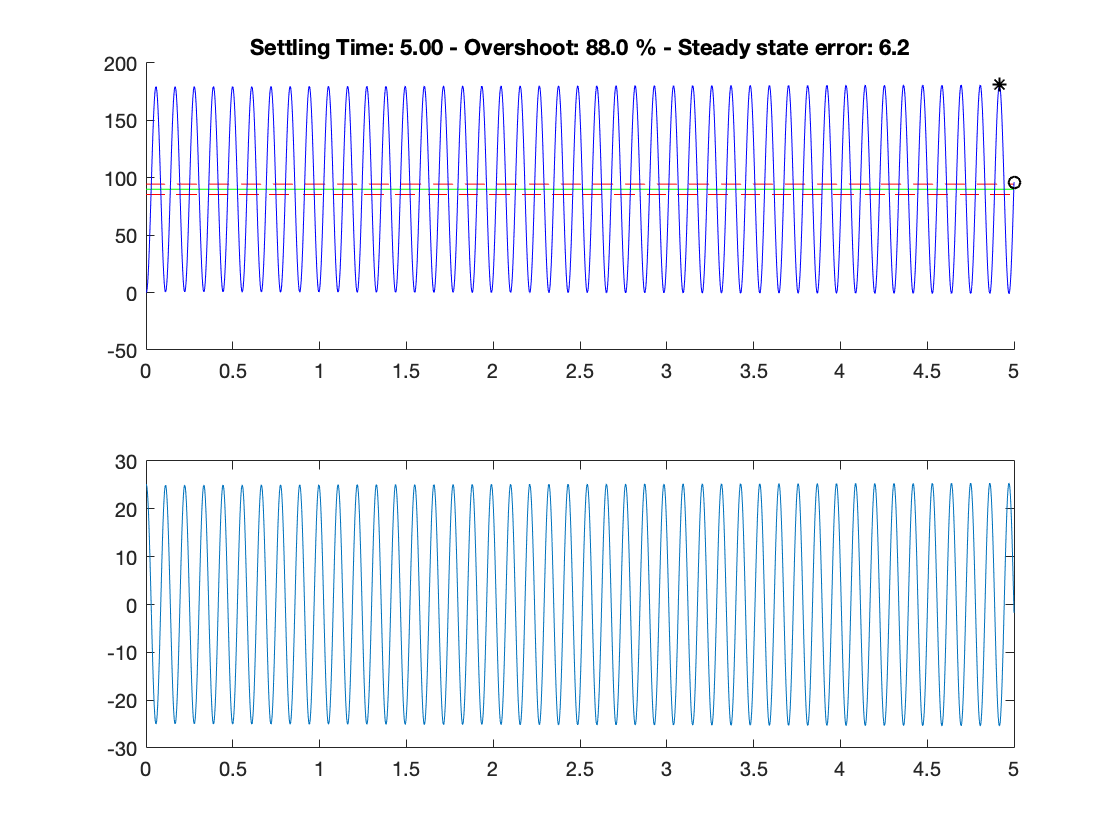



dt = 1e-3;
t = 0:dt:5;
r = 90 * pi / 180 * ones(size(t));
Hcl = feedback(K*Hol, 1);
y = lsim(Hcl, r, t);
u = lsim(feedback(K, Hol), r, t);
settlingTimeIdx = find(y(:) < 0.95*r(:) | y(:) > 1.05*r(:), 1, 'last');
[~, overshootIdx] = max(y);
steadyStateError = (180 / pi) * (y(end) - r(end));

figure(13);
clf;
hold on;
subplot(2, 1, 1)
title(sprintf('Settling Time: %3.2f - Overshoot: %03.1f %% - Steady state error: %3.1f', ...
    t(settlingTimeIdx), ...
    100*(y(overshootIdx) - y(end))/y(end), ...
    steadyStateError))
hold on;
plot(t, (180 / pi)*0.95*r, '--r');
plot(t, (180 / pi)*1.05*r, '--r');
plot(t, (180 / pi)*r, 'g');
plot(t, (180 / pi)*y, 'b');
plot(t(settlingTimeIdx), (180 / pi)*y(settlingTimeIdx), 'ok')
plot(t(overshootIdx), (180 / pi)*y(overshootIdx), '*k')
subplot(2, 1, 2)
plot(t, u);

% It can be seen by observing the above graph that as K deceases, the system becomes
% more stable

## **3 - Helpful Functions**

## *3.1 tf2str*

function str = tf2str(H)
fullStr = strrep(splitlines(string(evalc('H'))), ' ', '');
if contains(fullStr{4}, {'+', '-', '(', ')'})
    num = ['(', fullStr{4}, ')'];
else
    num = fullStr{4};
end
if contains(fullStr{6}, {'+', '-', '(', ')'})
    den = ['(', fullStr{6}, ')'];
else
    den = fullStr{6};
end
str = string([num, '/', den]);
end

## *3.2 customizeNyquistPlot*

function customizeNyquistPlot(H, XLim, YLim)
if nargin < 2
    XLim = [-2.2, 1.2];
end
if nargin < 3
    YLim = [-1.2, 1.2];
end

h = findall(gcf, 'Type', 'Patch');
for j = 1:length(h)
    h(j).LineWidth = 1.0;
end
h = findall(gcf, 'Type', 'line');
for j = 1:length(h)
    h(j).LineWidth = 1.5;
end
ax = findall(gcf, 'Type', 'Axes');
for j = 1:length(ax)
    ax(j).LineWidth = 1.2;
    ax(j).FontSize = 14;
end
hold on
plot(-1, 0, 'r+', 'linewidth', 2.0, 'markersize', 12)
hold off
xlim(XLim);
ylim(YLim);
title(sprintf('Nyquist Diagram for L = %s', tf2str(H)), 'fontsize', 14);
set(gcf, 'Visible', 'on');
end